# A Single Pulse Plot with the thresholds of each algorithm

## Algorithm Parameters

clear all;
close all;


PFA = 10^-3 ;
RefWindowSizeCA = 34; %reference window length
RefWindowSizeOS = 38;
GuardCells = 2; % Number of guard cells on each

% trimming variables:

T1 = 0;
T2 = 6;

## Load in Dataset

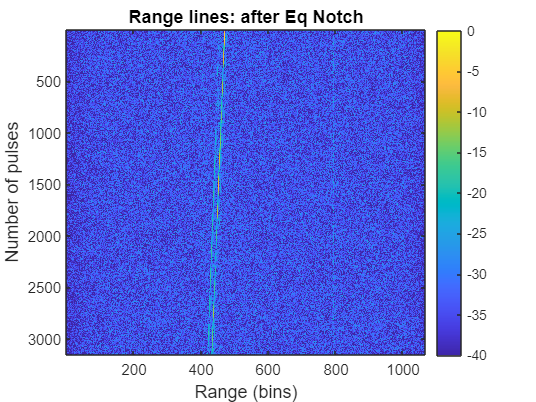



%% Load Data
[FileName,Path2RadarData,filter_index]=uigetfile('','Select Radar Dataset');
RadarData = load([Path2RadarData filesep FileName]);

%% Extract Range Profiles before, after Equalisation and after Notch filtering

RangeProfiles_BeforeEq = RadarData.RangeLines_BeforeEq;
RangeProfiles_AfterEq = RadarData.RangeLines_AfterEq;
RangeProfiles_AfterEqNotch = RadarData.RangeLines_AfterEQ_Notch;

%% Extract other radar parameters

 PRF_Hz = RadarData.Info.PRF_Hz;
 Bandwidth_Hz = RadarData.Info.Bandwidth_Hz;
 RangeStart_m = RadarData.Info.RangeStart_m;
 BlindRange_m = RadarData.Info.BlindRange_m;
 
[NumOfPulses,NumOfRangeBins]=size(RangeProfiles_AfterEqNotch);

fontsize1 = 12;
[MaxRangeLine MaxIdx] = max(max(abs(RangeProfiles_AfterEqNotch)));
clims = [-40 0];
figure; axes('fontsize',fontsize1);
imagesc(20*log10(abs(RangeProfiles_AfterEqNotch)./MaxRangeLine),clims);
colorbar;
xlabel('Range (bins)','fontsize',fontsize1);
ylabel('Number of pulses','fontsize',fontsize1);
title('Range lines: after Eq Notch','fontsize',fontsize1);
hold off 

## Running the Algorithms on the Dataset

% CA-CFAR
wrapFactor = RefWindowSizeCA/2 +GuardCells;
RangeProfiles_AfterEq=  horzcat(RangeProfiles_AfterEqNotch(:, end-wrapFactor+1:end), RangeProfiles_AfterEqNotch(:, 1:end), RangeProfiles_AfterEqNotch(:,1:wrapFactor));
[Detection_matrixCA, detection_count_matrixCA, ThresholdCA] = CA_CFAR_2D(RangeProfiles_AfterEq, PFA, RefWindowSizeCA, GuardCells);
Detection_matrixCA = Detection_matrixCA(:, wrapFactor+1:end-wrapFactor);
ThresholdCA = ThresholdCA(:, wrapFactor+1:end-wrapFactor);

% OS-CFAR
wrapFactor = RefWindowSizeCA/2 +GuardCells;
RangeProfiles_AfterEq=  horzcat(RangeProfiles_AfterEqNotch(:, end-wrapFactor+1:end), RangeProfiles_AfterEqNotch(:, 1:end), RangeProfiles_AfterEqNotch(:,1:wrapFactor));
[Detection_matrixOS, detection_count_matrixOS, ThresholdOS] = OS_CFAR_2D(RangeProfiles_AfterEq, PFA, RefWindowSizeCA, GuardCells);
Detection_matrixOS = Detection_matrixOS(:, wrapFactor+1:end-wrapFactor);
ThresholdOS = ThresholdOS(:, wrapFactor+1:end-wrapFactor);

% TM-CFAR
wrapFactor = RefWindowSizeCA/2 +GuardCells;
RangeProfiles_AfterEq=  horzcat(RangeProfiles_AfterEqNotch(:, end-wrapFactor+1:end), RangeProfiles_AfterEqNotch(:, 1:end), RangeProfiles_AfterEqNotch(:,1:wrapFactor));
[Detection_matrixTM, detection_count_matrixTM, ThresholdTM] = TM_CFAR_2D(RangeProfiles_AfterEq, PFA, RefWindowSizeCA, GuardCells, T1, T2);
Detection_matrixOS = Detection_matrixOS(:, wrapFactor+1:end-wrapFactor);
ThresholdTM = ThresholdTM(:, wrapFactor+1:end-wrapFactor);


## Plotting the thresholds

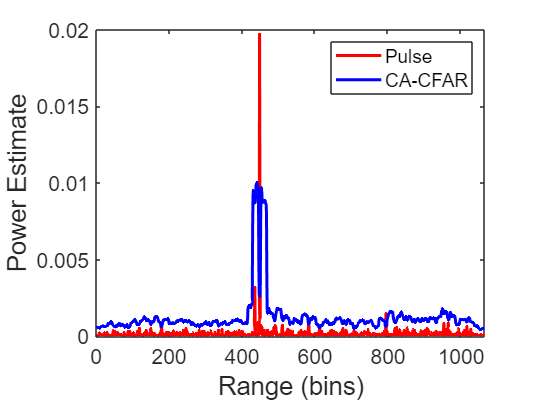

DataAfterPowerLawDetector = abs(RangeProfiles_AfterEqNotch).^2 ;

figure;
pulse = 1817;

% Plot the first line (red)
plot(DataAfterPowerLawDetector(pulse, :), 'Color', 'red', 'LineWidth', 2);
hold on; % To keep the current plot active for additional lines

% Plot the second line (blue)
plot(ThresholdCA(pulse, :), 'Color', 'blue', 'LineWidth', 2);

% % % Plot the third line (green)
% plot(ThresholdOS(pulse, :), 'Color', 'green', 'LineWidth', 2);
% % 
% % % Plot the fourth line (green)
% plot(ThresholdTM(pulse, :), 'Color', 'magenta', 'LineWidth', 2);

% Add legend labels
% legend('Pulse', 'CA-CFAR', 'OS-CFAR', 'TM-CFAR' );
legend('Pulse', 'CA-CFAR');

% Add labels and title
set(gca, 'FontSize', 14);
xlabel('Range (bins)', 'FontSize', 17);
ylabel('Power Estimate', 'FontSize', 17);
%title('Plot of a Single Pulse and Algorithm Detection Thresholds');

hold off;

## Functions

function [Detections, detection_count, threshold] = CA_CFAR_2D(input, PFA, RefWindowSize, GuardCells)
TrainCells = (RefWindowSize)/2; % Number of training cells in reference window
[numRows,numCols] = size(input);
threshold = zeros(numRows, numCols);
Detections = zeros(numRows, numCols);
detection_count = zeros(numRows, 1);

%the CA-CFAR constant (α) 
alpha = RefWindowSize*(PFA^(-1/RefWindowSize) - 1);

%square law detector.
DataAfterPowerLawDetector = abs(input).^2 ;

%the CA-CFAR constant (α) 
startIndx = RefWindowSize/2 + GuardCells+ 1;
stopIndx = numCols - RefWindowSize/2 - GuardCells;

for i = (startIndx):(stopIndx)
    % Calculate average of reference cells in the leading and lagging windows
    reference_avg_leading = sum(DataAfterPowerLawDetector(:, i + GuardCells + 1 : i + GuardCells + RefWindowSize/2),2) ./ TrainCells;
    reference_avg_lagging = sum(DataAfterPowerLawDetector(:, i - RefWindowSize/2 - GuardCells: i - GuardCells - 1),2) ./ TrainCells;

    % Calculate threshold using scaling factor
    threshold(:, i) = alpha.*((reference_avg_leading + reference_avg_lagging) ./ 2);

    %Detection calculated
    Detections(:,i) = DataAfterPowerLawDetector(:, i) > threshold(:, i);
    detection_count = detection_count + Detections(:,i);

 
end

end



function [Detections, detection_count, Threshold] = OS_CFAR_2D(input, PFA, RefWindowSize, GuardCells)
[numRows,numCols] = size(input);
Threshold = zeros(numRows, numCols);
Detections = zeros(numRows, numCols);
detection_count = zeros(numRows, 1);
K = zeros(numRows, 1);
k = round(3/4*RefWindowSize);

%Square Law detector:
DataAfterPowerLawDetector = abs(input).^2 ;

% Threshold factor:
syms aos p %creation of symbolic variables used in equation
f = symprod((RefWindowSize-p)/(RefWindowSize-p+aos), p, 0, k-1) - PFA; %equation to find threshold factor
fhandle = matlabFunction(f); %create function handle linked to equation
initial_guess = 5;
root = fzero(fhandle, initial_guess); %root of equation is the threshold factor
alpha = root;

%Start and Stop Indices for algorthm:
startIndx = RefWindowSize/2 + GuardCells+ 1;
stopIndx = numCols - RefWindowSize/2 - GuardCells;

% Threshold calculation:
for i = (startIndx):(stopIndx)
    %Sort reference window into ascending order
    RefWindowLead = DataAfterPowerLawDetector(:, i + GuardCells + 1 : i + GuardCells + RefWindowSize/2);
    RefWindowLag = DataAfterPowerLawDetector(:, i - RefWindowSize/2 - GuardCells: i - GuardCells - 1);
    RefWindow = horzcat(RefWindowLag, RefWindowLead);
    sorted_RefWindow = sort(RefWindow, 2);
    %sorted_RefWindow = reshape(sorted_RefWindow, size(RefWindow)); 

    %Finding Kth element
    K = sorted_RefWindow(:, k);

    % Calculate threshold using scaling factor
    Threshold(:, i) = alpha.*K;
    
    %Detection calculated
    Detections(:,i) = DataAfterPowerLawDetector(:, i) > Threshold(:, i);
    detection_count = detection_count + Detections(:,i);
end

end





function [Detections, detection_count, Threshold] = TM_CFAR_2D(input, PFA, RefWindowSize, GuardCells, T1, T2)
[numRows,numCols] = size(input);
Threshold = zeros(numRows, numCols);
Detections = zeros(numRows, numCols);
detection_count = zeros(numRows, 1);

%Square Law detector:
DataAfterPowerLawDetector = abs(input).^2 ;


% Threshold factor:
syms T p;
M1 = symprod((RefWindowSize-p)/(RefWindowSize+T*(RefWindowSize -T1 -T2) - p), p, 0, T1);
Mi = symprod(((RefWindowSize - T1 - p +1)/(RefWindowSize - T1 - T2 - p +1))/(((RefWindowSize - T1 - p +1)/(RefWindowSize - T1 - T2 - p +1))+T), p, 2, RefWindowSize - T1 - T2);
f = M1*Mi - PFA;
fh = matlabFunction(f);
root = fzero(fh, 5);
alpha = root;

%Start and Stop Indices for algorthm:
startIndx = RefWindowSize/2 + GuardCells+ 1;
stopIndx = numCols - RefWindowSize/2 - GuardCells;

% Threshold calculation:
for p = (startIndx):(stopIndx)
    % Calculate the reference cells in the leading and lagging windows
    reference_leading = (DataAfterPowerLawDetector(:, p + GuardCells + 1 : p + GuardCells + RefWindowSize/2));
    reference_lagging = (DataAfterPowerLawDetector(:, p - RefWindowSize/2 - GuardCells: p - GuardCells - 1));

    %Trimming of reference window
    reference_window = horzcat(reference_lagging, reference_leading);
    reference_window = sort(reference_window, 2);
    reference_window_trimmed = reference_window(:, 1+T1:end - T2);
    reference_window_sum = sum(reference_window_trimmed, 2);


    % Calculate threshold using scaling factor
    Threshold(:, p) = alpha.*reference_window_sum;

    %Detection calculated
    Detections(:,p) = DataAfterPowerLawDetector(:, p) > Threshold(:, p);
    detection_count = detection_count + Detections(:,p);
end
Threshold_ave = (sum(Threshold(:)))/(numCols*numRows);
end


